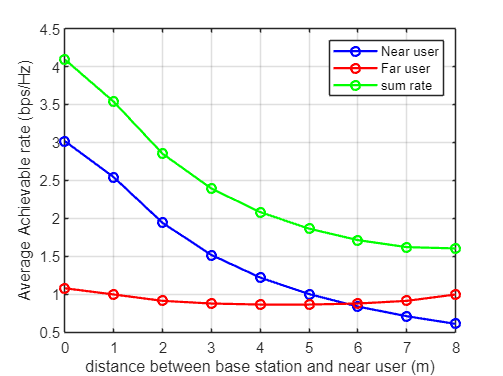

clc; clear variables; close all;

 
%source, 2 users. strong user acts as energy harvesting 
%relay to weak.  have direct path from BS to far user


N = 10^6;   

dsn = 0:1:8;   %Source to near user distance    
dsf = 9;   %Source to far user distance
dnf = dsf - dsn; %Near user to far user distance
eta = 2;    %Path loss exponent
%Rayleigh fading coefficients
hsn = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsn = (abs(hsn)).^2;
hsf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsf = (abs(hsf)).^2;
hnf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gnf = (abs(hnf)).^2;



Pt = 30;    % 发送功率（dBm）
pt = 10.^(Pt/10);    % 发送功率（线性尺度）
N0_dBm=1;                % Noise spectral density (in dBm/Hz)
N0=10^(N0_dBm/10);          % Linear noise PSD in mW/Hz
snr =  pt/N0;  %SNR in linear

%Power allocation factors
af = 0.8; an = 0.2;
R1 = 0.3; %Target rate for far user
t1 = (2^(2*R1))-1;   %target snr for both users
R2 = 1;   %target rate for near user
t2 = (2^(2*R2))-1;
eff = 0.7;  %power harvesting efficiency of the near user
frac = 0.3; %power splitting coefficient
del = 10^-6; %a small number

%Some buffers
pn = zeros(1,length(dsn));
pf = zeros(1,length(dsn));

cn = zeros(1,length(dsn));
cf = zeros(1,length(dsn));
cph = zeros(1,length(dsn));
sum = zeros(1,length(dsn));

for u = 1:length(dsn)    
   
    

    %Amount of power harvested by near user
    ph = pt*gsn.*frac*eff/(1+dsn(u)^eta);
    

    %SNIR for each user
    SNRnf = af*snr *(1-frac).*gsn./(snr .*(an*(1-frac).*gsn) + (1+dsn(u)^eta));
    SNRnf1 = af*snr .*gsn./(snr .*(an*gsn) + (1+dsn(u)^eta));
    SNRnn = an*snr *(1-frac).*gsn/(1+dsn(u).^eta);
    SNRsf = af*snr .*gsf./(snr .*an.*gsf+1+dsf^eta);
    SNRfmrc = SNRsf + (eff*snr .*gnf.*frac.*gsn./((1+dsn(u).^eta)*(1+dnf(u).^eta)));

    %Achievable rate of near user
    Rnf = 0.5 *log2(1 + SNRnf);
    Rnn = 0.5 *log2(1 + SNRnn);
    Rnf1 = 0.5 * log2(1 + SNRnf1);
    %Achievable rate of far user
    Rf = 0.5 *log2(1 + SNRfmrc);
    Rsf = 0.5*log2(1 + SNRsf);
    cn(u) = mean(Rnn);
    cf(u) = mean(Rf);
    cph(u) = mean(ph);
    sum(u) = cn(u)+cf(u);
    
    for k=1:N
       if (  Rf(k)<R1) &&(SNRnf(k)>R1)
          pf(u) = pf(u) + 1;
       end
        if (Rsf(k) < R1)&&(Rnf(k)<R1)
          pf(u) = pf(u) + 1;
        end
        if Rnf1(k)<R1 
          pn(u) = pn(u) + 1;
       end
        if (Rnf1(k) > R1)&&(Rnn(k)<R2)
          pn(u) = pn(u) + 1;
       end

    end

    
end

poutn1 = pn/N;
poutf1 = min(pf/N,1);

 

figure;
plot(dsn, cn, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
plot(dsn, cf, 'r-o', 'LineWidth', 1.5, 'MarkerSize', 6);
plot(dsn, sum, 'g-o', 'LineWidth', 1.5, 'MarkerSize', 6);
legend('Near user','Far user','sum rate');
xlabel('distance between base station and near user (m)');
ylabel('Average Achievable rate (bps/Hz)');
xlim([0 8]); % 设置 x 轴范围
xticks(0:1:8); % 设置 x 轴刻度间隔

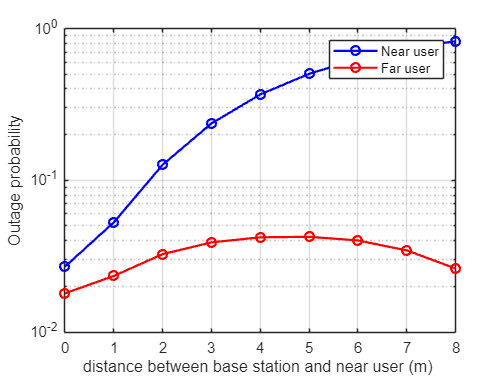


figure;
semilogy(dsn, poutn1, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
semilogy(dsn, poutf1, 'r-o', 'LineWidth', 1.5, 'MarkerSize', 6);
legend('Near user','Far user');
xlabel('distance between base station and near user (m) ');
ylabel('Outage probability');
xlim([0 8]); % 设置 x 轴范围
xticks(0:1:8); % 设置 x 轴刻度间隔